## Part 1:

### 1.

#### a.

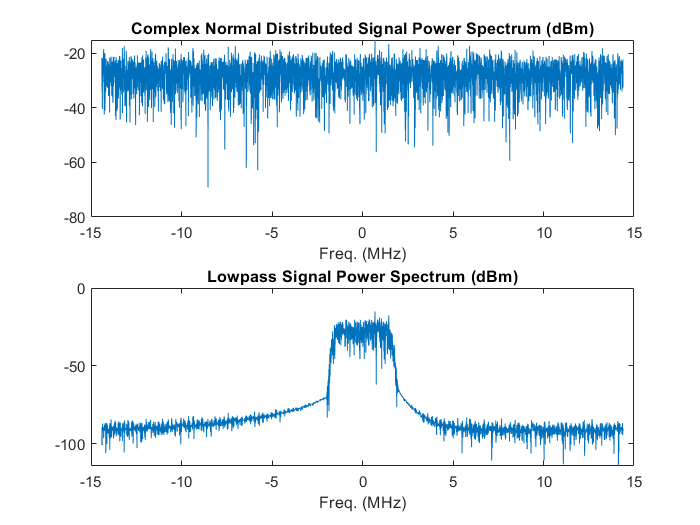

x = (randn(4096, 1) + randn(4096, 1) * 1j)/sqrt(2);
y = conv(x, lp_filter, 'same');
fs = 28.8;
n_fft = 4096;
freq = ((0:n_fft-1)/n_fft * fs - fs/2);
Xf = fftshift(fft(x, n_fft))/4096;
Yf = fftshift(fft(y, n_fft))/4096;
Sx_dBm = 10*log10(abs(Xf).^2/100) + 30;
Sy_dBm = 10*log10(abs(Yf).^2/100) + 30;

figure
subplot(2,1,1);
plot(freq, Sx_dBm)
xlabel('Freq. (MHz)')
title('Complex Normal Distributed Signal Power Spectrum (dBm)')

subplot(2,1,2); 
plot(freq, Sy_dBm)
xlabel('Freq. (MHz)')
title('Lowpass Signal Power Spectrum (dBm)')


x_power = sum(abs(x).^2)/4096

x_power = 0.9994

lowpass_filtered_x_power = sum(abs(y).^2)/4096

lowpass_filtered_x_power = 0.1087

noise_BW = noisebw(lp_filter, 1, 4096, fs*10^6) 

noise_BW = 3.3081e+06

#### به دلیل اینکه با عبور فرآیند تصادفی از فیلتر دامنه ی فرکانسی آن محدود می شود، پس در نتیجه ی آن توان سیگنال خروجی متناسب با پهنای باند معادل (پهنای باند نویز) فیلتر خواهد بود. 

#### b.

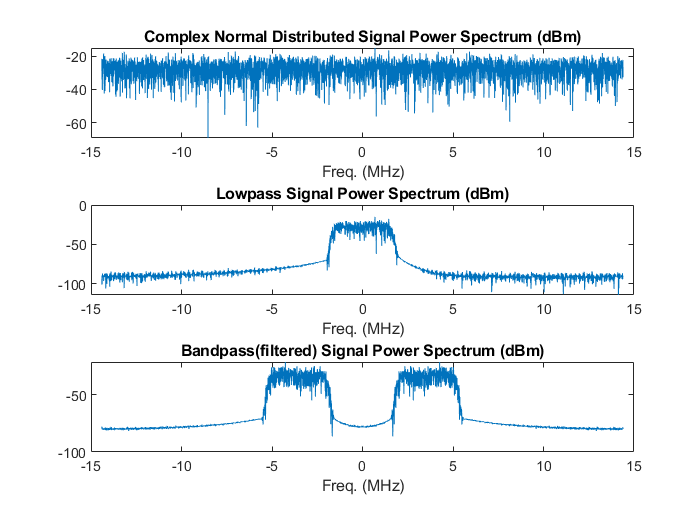

fc = 3.57;
n = ((0:4095)/fs).';
x_bp = real(y.*exp(2*pi*fc*n*1j));
Xf_bp = fftshift(fft(x_bp, n_fft))/4096;
Sx_bp_dBm = 10*log10(abs(Xf_bp).^2/100) + 30;

figure
subplot(3, 1, 1);
plot(freq, Sx_dBm)
xlabel('Freq. (MHz)')
title('Complex Normal Distributed Signal Power Spectrum (dBm)')

subplot(3, 1, 2); 
plot(freq, Sy_dBm)
xlabel('Freq. (MHz)')
title('Lowpass Signal Power Spectrum (dBm)')

subplot(3, 1, 3); 
plot(freq, Sx_bp_dBm)
xlabel('Freq. (MHz)')
title('Bandpass(filtered) Signal Power Spectrum (dBm)')


x_power = sum(abs(x).^2)/4096

x_power = 0.9994

lowpass_filtered_x_power = sum(abs(y).^2)/4096

lowpass_filtered_x_power = 0.1087

x_bp_power = sum(abs(x_bp).^2)/4096

x_bp_power = 0.0543

#### مطابق انتظار توان فرآیند میان گذر یک دوم توان فرآیند پایین گذر معادل آن است. چرا که هنگام محاسبه ی فرآیند پایین گذر از دو سیگنال عمود بر هم استفاده می شود که توان هر کدام یک چهارم توان فرآیند میان گذر هستند پس جمع آن ها معادل یک دوم توان فرآیند میان گذر است.

#### c.

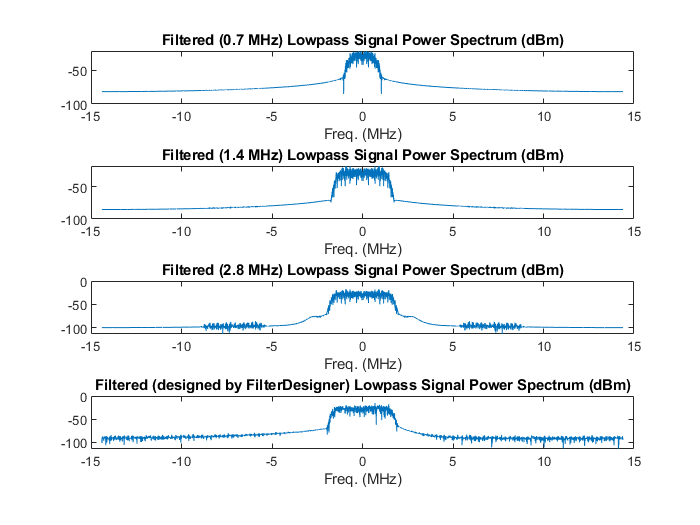

x_lp = 2 * x_bp .* (cos(2*pi*fc*n) - sin(2*pi*fc*n));
h1 = fir1(120, 1.4/fs);
y1 = conv(x_lp, h1, 'same');
h2 = fir1(120, 2.8/fs);
y2 = conv(x_lp, h2, 'same');
h3 = fir1(120, 5.6/fs);
y3 = conv(x_lp, h3, 'same');
Y1f = fftshift(fft(y1, n_fft))/4096;
Y2f = fftshift(fft(y2, n_fft))/4096;
Y3f = fftshift(fft(y3, n_fft))/4096;
Sy1_dBm = 10*log10(abs(Y1f).^2/100) + 30;
Sy2_dBm = 10*log10(abs(Y2f).^2/100) + 30;
Sy3_dBm = 10*log10(abs(Y3f).^2/100) + 30;

figure
subplot(4,1,1);
plot(freq, Sy1_dBm)
xlabel('Freq. (MHz)')
title('Filtered (0.7 MHz) Lowpass Signal Power Spectrum (dBm)')

subplot(4,1,2); 
plot(freq, Sy2_dBm)
xlabel('Freq. (MHz)')
title('Filtered (1.4 MHz) Lowpass Signal Power Spectrum (dBm)')

subplot(4,1,3);
plot(freq, Sy3_dBm)
xlabel('Freq. (MHz)')
title('Filtered (2.8 MHz) Lowpass Signal Power Spectrum (dBm)')

subplot(4,1,4); 
plot(freq, Sy_dBm)
xlabel('Freq. (MHz)')
title('Filtered (designed by FilterDesigner) Lowpass Signal Power Spectrum (dBm)')


y1_0p7_power = sum(abs(y1).^2)/4096

y1_0p7_power = 0.0401

y2_1p4_power = sum(abs(y2).^2)/4096

y2_1p4_power = 0.0951

y3_2p8_power = sum(abs(y3).^2)/4096

y3_2p8_power = 0.1110

lowpass_filtered_x_power = sum(abs(y).^2)/4096 %from part a

lowpass_filtered_x_power = 0.1087

#### مشابه قسمت اول با عبور فرآیند از فیلتر توان فرآیند کاهش می باید و چون توان فرآیند فیلتر شده متناسب با پهنای باند فیلتر است، پس با افزایش پهنای باند مشاهده می کنیم که توان فرآیند فیلتر شده افزایش یافته و به مقدار توان فرآیند ورودی نزدیک تر می شود. به دلیل این که پهنای باند فیلتر جدید که 2.8 مگاهرتز است به پهنای باند معادل فیلتر اولیه که حدودا 3.3 مگا هرتز است ، نزدیک تر است و اتلاف توان کمتر ی رخ می دهد.